# Basic primitives usage example

#### Common setup for all examples

ex_setup

Setup complete


#### Start timer

tic

#### Povlab object

pl = povlab( povray_version,...
             povray_path, ...
             povray_out_dir);

#### Scene

pl.scene_begin('scene_file', 'primitives.pov', 'image_file', 'primitives.png');
    pl.include("shapes");
    
    pl.global_settings("assumed_gamma 1");

    % Axis
    % pl.axis('radius', 0.1, 'length', [5 3.5 6]);

    % Camera
    pl.camera('angle', 37, 'location', [28 14 10], 'look_at', [0 6 5.5], 'type', 'perspective');
    
    % Camera: look at YZ plane
    % pl.camera('angle', 40, 'location', [70 5 2], 'look_at', [28 5 2], 'type', 'orthographic');
    
    % Camera: look at XZ plane
    % pl.camera('angle', 40, 'location', [0 40 2], 'look_at', [0 0 2], 'type', 'orthographic');
    
    % Lights
    pl.light('location', [100 100 300], 'color', [0.4 0.4 0.4], 'shadowless', false);
    pl.light('location', [28 14 10], 'color', [0.2 0.2 0.2], 'shadowless', true);
    
    % Floor and wall
    tex_checker = pl.declare("tex_floor", pl.texture('pigment_odd', [2.8 2.8 2.8], 'pigment_even', [0.1 0.1 0.1]));
    pl.plane('normal', [0,0,1], 'distance', 0,   'texture', tex_checker);
    pl.plane('normal', [1,0,0], 'distance', -10, 'texture', tex_checker, 'translate', [0 0 1]);

    % Textures
    finish = "phong 1 reflection {0.04 metallic 0.4}";
    tex_sphere     = pl.declare("tex_sphere",     pl.texture('pigment', [3 0.15 0],    'finish', finish));
    tex_cylinder   = pl.declare("tex_cylinder",   pl.texture('pigment', [0 2 0],       'finish', finish));
    tex_cone       = pl.declare("tex_cone",       pl.texture('pigment', [0 0.5 4],     'finish', finish));
    tex_cone_trunc = pl.declare("tex_cone_trunc", pl.texture('pigment', [0 2 4],       'finish', finish));
    tex_box        = pl.declare("tex_box",        pl.texture('pigment', [6.24 2.34 0], 'finish', finish));
    tex_torus      = pl.declare("tex_torus",      pl.texture('pigment', [7.3 1.8 2.7], 'finish', finish));

    % Objects
    pl.cylinder('base_point', [0 0 0], 'cap_point', [0 0 5], 'radius', 1.8, 'texture', tex_cylinder);
    pl.box('llf_corner', [1.7 -1.7 0], 'urb_corner', [-1.7 1.7 3.4] , 'texture', tex_box, 'translate', [0 0 7]);

    pl.cone('base_point', [0 0 0], 'base_radius', 1.8, 'cap_point', [0 0 6.5], 'texture', tex_cone, 'translate', [0 6 0]);
    pl.torus('radius_maj', 1.8, 'radius_min', 0.9, 'texture', tex_torus, 'rotate', [90 30 0], 'translate', [0 6 9]);

    pl.cone('base_point', [0 0 0], 'base_radius', 1.8, 'cap_point', [0 0 5.5], 'cap_radius', 0.85, 'texture', tex_cone_trunc, 'translate', [0 12 0]);
    pl.sphere('position', [0 0 0], 'radius', 2, 'texture', tex_sphere, 'translate', [0 12 9]);

pl.scene_end();

#### Render and display

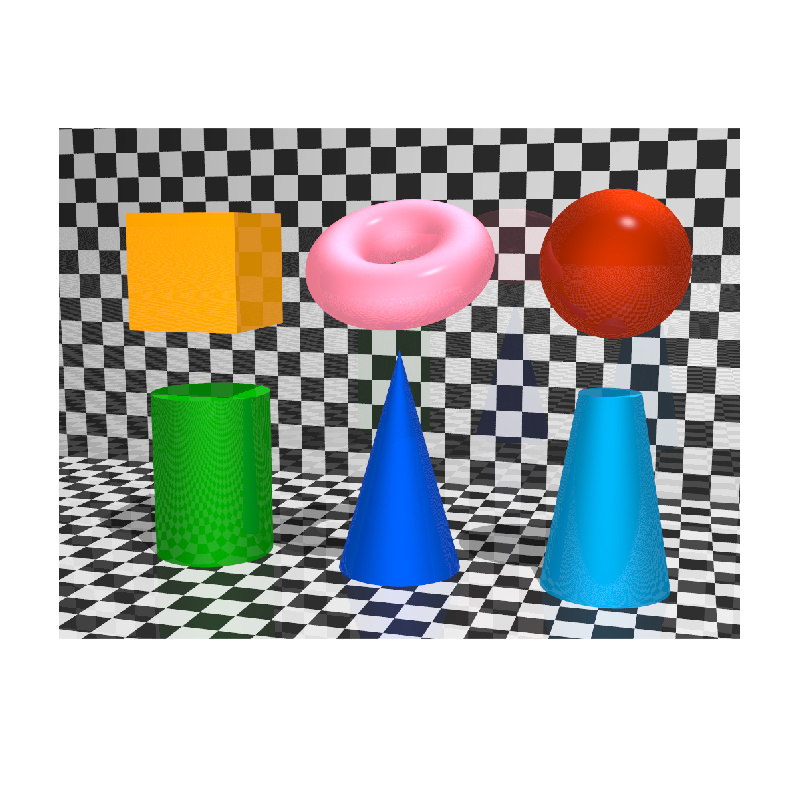

img = pl.render();
imshow(img);

#### Elapsed time

toc

Elapsed time is 4.999736 seconds.
